BBE_st.name='BBE'; 
BBE_st.lat=29.30;
BBE_st.lon=-103.18;
BBE_st.alt=1066;
BBE_st.env='con';
BBE_st.footp='DE';

BBE_rd=read_betsy('BBE_head',BBE_st.name);

datevec(BBE_rd.Time(1))

ans =         1998           1           2           0           0           0

datevec(BBE_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(BBE_rd.U_S,[5, 50, 95])

ans =    13.5650   40.8425   78.4650

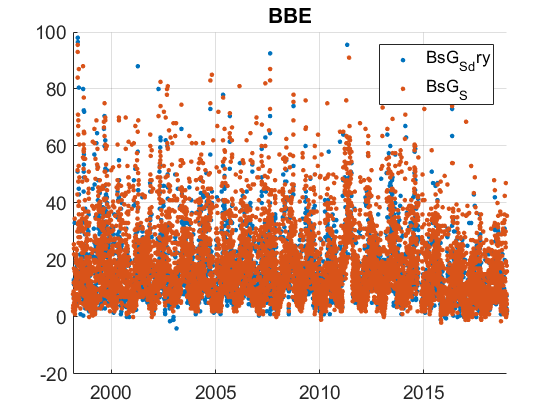

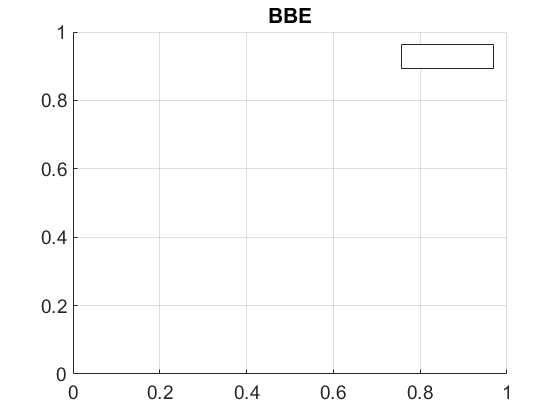

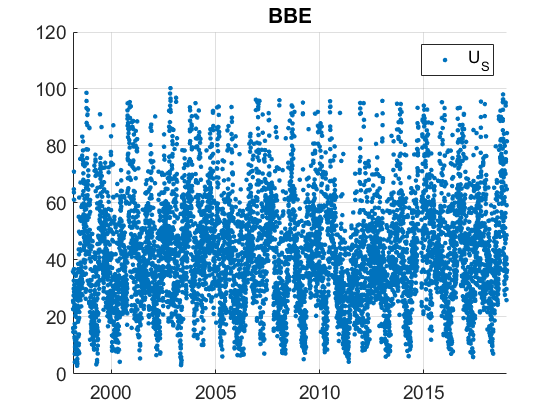

plotFigControl(BBE_rd,BBE_st.name);

% 1 size cut
% sc: ok, clear seasonal cycle in summer,

lambdaSC=[450;550;700]*ones(1,4); lambdaAE3=[467;530;660]*ones(1,4); lambdaAE7=[370 470 520 590 660 880 950]; BBE_cal=compute_exp_SSA(BBE_rd,lambdaSC, lambdaAE3); plotFigControl_cal(BBE_cal, BBE_st.name);

%Questions:
%problems:
% MINIMA higher in summer 2011 ?
%modification in 2016 ? rupture ?


BBE_tr=BBE_rd;
BBE_tr.y=year(BBE_tr.Time);
%eneleve une valeur de 2019
BBE_tr=BBE_tr(1:end-1,:);
% begin at the beginning of a year: 1998
%end: 2015: scat lower then, decreasing trend not trusted!
P=timerange('1998-01-01','2016-01-01');
BBE_tr=BBE_tr(P,:);
names=fieldnames(BBE_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    BBE_tr.(N{i})=[];
end
% 9.2.2011 to 23.7.2011 to delete ? wait for answer
P=timerange('2013-06-20','2013-09-30');
BBE_tr.BsG_S(P)=NaN;
BBE_tr.BsG_S_dry(P)=NaN;

%end 2015 (break point) ? wait for answer

%to evaluation otherwise no figure
BBE_result= all_trend_STN(BBE_tr,BBE_st); 

BBE_result_D=BBE_result;